# Periodic behaviour

a = 1;
c = 1;
d = 5; 
s = 4;
x0 =-1.6; 
b=4.3;
I=10;
e=0.0002;
f = @(t,X)hindmarsh_rose(t,X,[a,c,d,s,x0,b,I,e]); 
[T,X]=ode45(f,[0,500],[x0,10,10])

T =          0
    0.0032
    0.0064
    0.0096
    0.0128
    0.0271
    0.0414
    0.0556
    0.0699
    0.0919


X =    -1.6000   10.0000   10.0000
   -1.5224    9.9323   10.0000
   -1.4498    9.8684   10.0000
   -1.3816    9.8081   10.0000
   -1.3174    9.7508   10.0000
   -1.0675    9.5256   10.0000
   -0.8634    9.3392    9.9999
   -0.6899    9.1803    9.9999
   -0.5350    9.0390    9.9999
   -0.3194    8.8444    9.9999


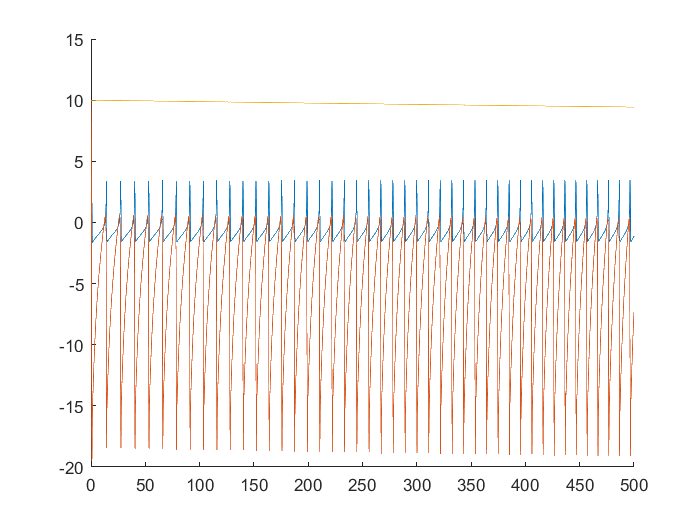


figure

hold on
plot(T,X(:,1))
plot(T,X(:,2))
plot(T,X(:,3))
hold off

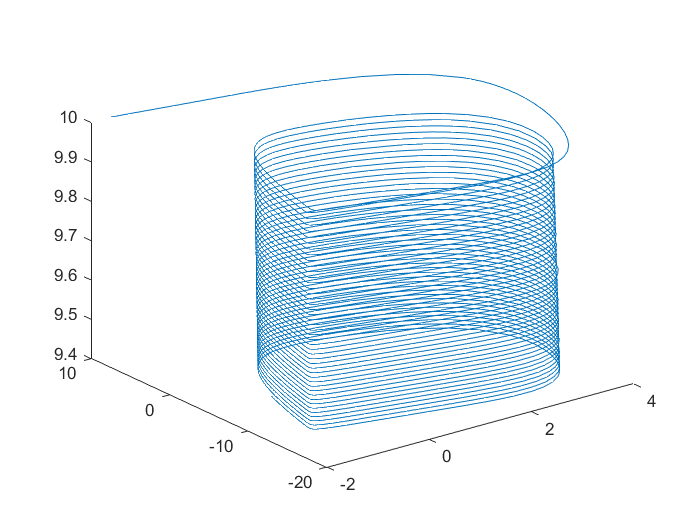


figure %Phase portrait 

plot3(X(:,1),X(:,2),X(:,3))

# Bursting behaviour

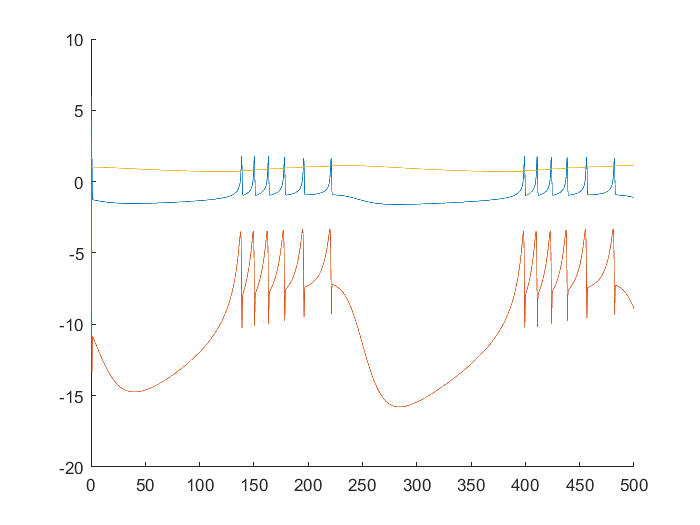

a = 1;
c = -3;
d = 5; 
s = 4;
x0 =-1.3; 
b=3;
I=5;
e=0.002;
f = @(t,X)hindmarsh_rose(t,X,[a,c,d,s,x0,b,I,e]); 
[T,X]=ode45(f,[0,500],[x0,6,1]);

figure 

hold on
plot(T,X(:,1))
plot(T,X(:,2))
plot(T,X(:,3))
hold off

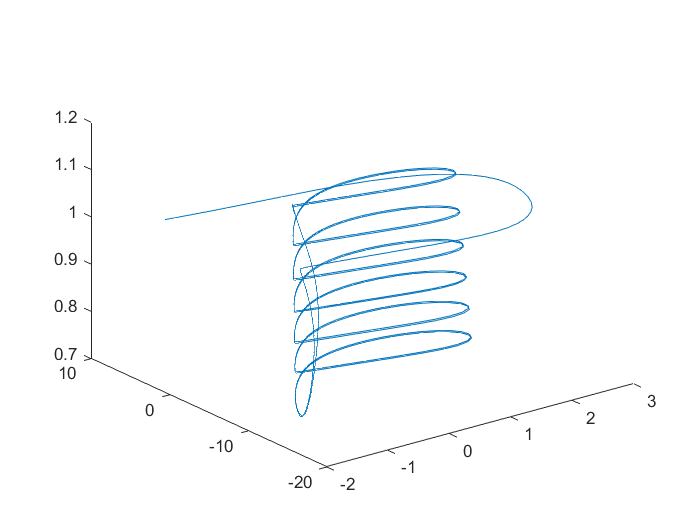


figure %Phase portrait

plot3(X(:,1),X(:,2),X(:,3))

## fsolve - *didn't use any of this*

%Solve three equations for equal to zero (this one is for periodic)
f = @(X)hindmarsh_rose(0,X,[1,1,5,4,-1.6,4.3,10,0.0002])

f = function_handle with value:
    @(X)hindmarsh_rose(0,X,[1,1,5,4,-1.6,4.3,10,0.0002])


x00=[100,100,100]

x00 =    100   100   100


x=fsolve(f,x00)


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



x =     0.8608   -2.7052    9.8434


%This is the coordiates of the point through which we draw a plane (parallel to z- and y- axis)
%This plane is used to draw Pontine'(??) map to determine is the function is chaotic (pattern) or not (point/line)

%Solve three equations for equal to zero (this one is for bursting)
a = 1;
c = -3;
d = 5; 
s = 4;
x0 =-1.3; 
b=3;
I=5;
e=0.002;

xi= [0,0,0]

xi =      0     0     0


fsolve(@(X)[X(2)-(a*(X(1))^3)+(b*(X(1))^2)-X(3)+I; c-d*(X(1))^2-X(2);e*(s*(X(1)-x0)-X(3))],[xi])


Equation solved.

fsolve completed because the vector of function values is near zero
as measured by the default value of the function tolerance, and
the problem appears regular as measured by the gradient.

<stopping criteria details>



ans =    -1.0652   -8.6728    0.9394





%find peaks for one dataset numerically - see where they match 
%then use loop to change parameters

# **Bifurcation**

## **Refine peaks**

a = 1;
c = -3;
d = 5; 
s = 4;
x0 =-1.3; 
b=3;
I=5;
e=0.002;
f = @(t,X)hindmarsh_rose(t,X,[a,c,d,s,x0,b,I,e]); 

%first solve with relaxed tolerances over long period
opts1 = odeset('RelTol',1e-6,'AbsTol',1e-8);
[~,X]=ode45(f,[0,2000],[x0;6;1],opts1);

%then use the evolved solution as the initial condition 
%with tighter tolerances and shorter period
opts2 = odeset('RelTol',1e-8,'AbsTol',1e-10);
[T,X]=ode45(f,[0,500],X(end,:),opts2)

T =          0
    0.0167
    0.0334
    0.0501
    0.0668
    0.0835
    0.1002
    0.1169
    0.1336
    0.1560


X =    -0.8245   -6.6010    0.9713
   -0.8241   -6.5976    0.9713
   -0.8236   -6.5942    0.9713
   -0.8231   -6.5909    0.9714
   -0.8227   -6.5875    0.9714
   -0.8222   -6.5841    0.9714
   -0.8217   -6.5806    0.9715
   -0.8212   -6.5772    0.9715
   -0.8208   -6.5738    0.9715
   -0.8201   -6.5692    0.9716


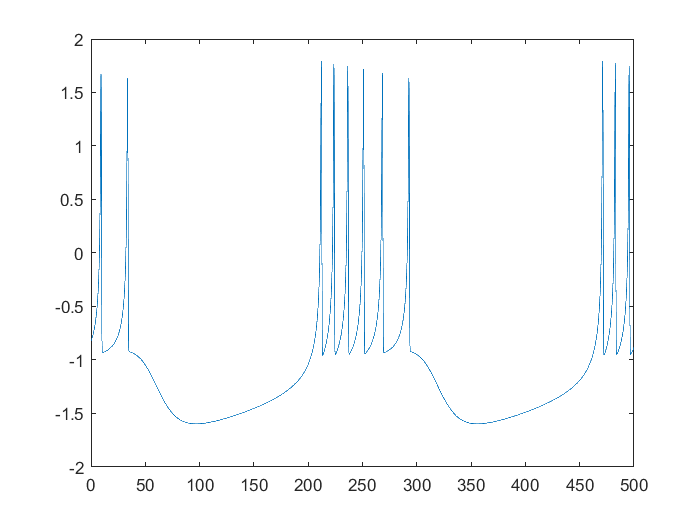


figure
plot(T,X(:,1))

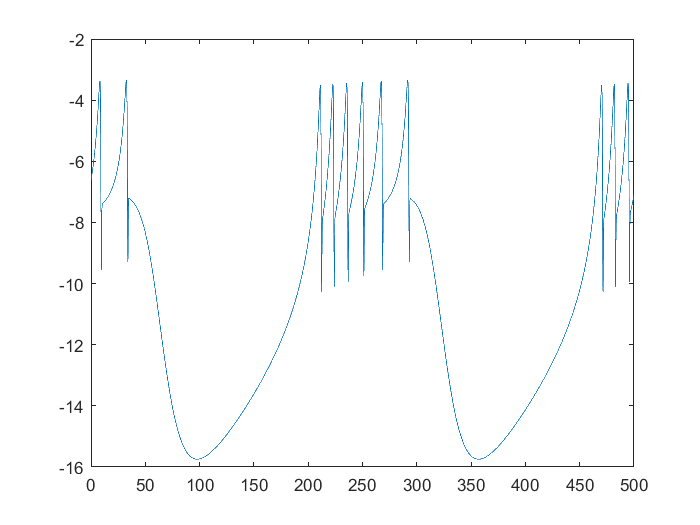


figure
plot(T,X(:,2))



%[T,X]=ode45(f,[0,500],[x0,6,1]);

%peaks location for X(:,1)
[pks1,loc1]=findpeaks(X(:,1),T)

pks1 =     1.6764
    1.6332
    1.7940
    1.7690
    1.7417
    1.7113
    1.6764
    1.6332
    1.7940
    1.7690


loc1 =     9.2212
   33.6574
  212.0852
  223.6718
  236.4514
  250.9506
  268.2914
  292.7301
  471.1535
  482.7384


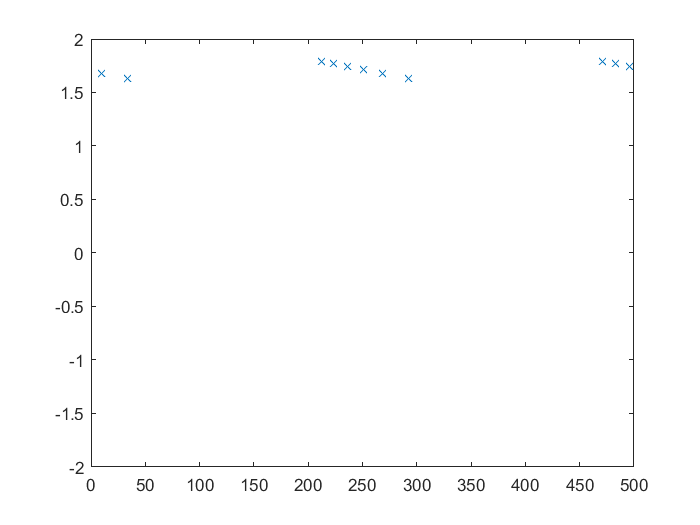

figure
plot(loc1,pks1,'X')
ylim([-2,2])


%peaks location for X(:,2)
[pks2,loc2]=findpeaks(X(:,2),T)

pks2 =    -3.3782
   -3.3402
   -7.2167
   -3.5085
   -3.4772
   -3.4453
   -3.4126
   -3.3782
   -3.3402
   -7.2167


loc2 =     8.1830
   32.5818
   35.0026
  211.1642
  222.7337
  235.4894
  249.9552
  267.2521
  291.6402
  294.0752


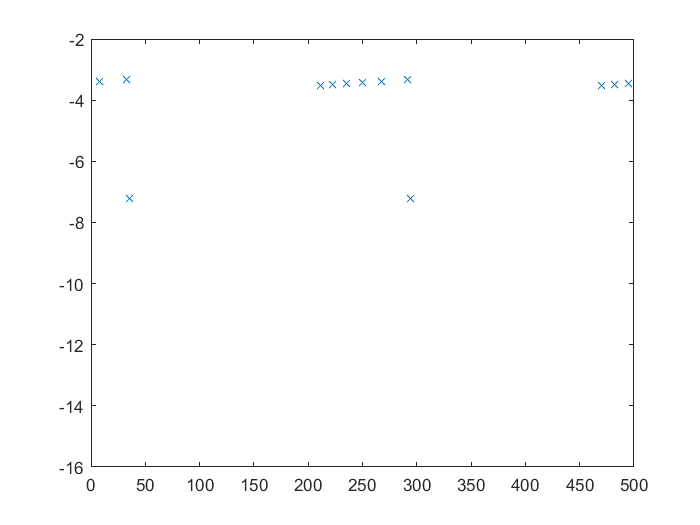

figure
plot(loc2,pks2,'X')
ylim([-16,-2])


%peaks location for X(:,3)
[pks3,loc3]=findpeaks(X(:,3),T)

pks3 =     1.1191
    1.1191


loc3 =    48.1419
  307.2171


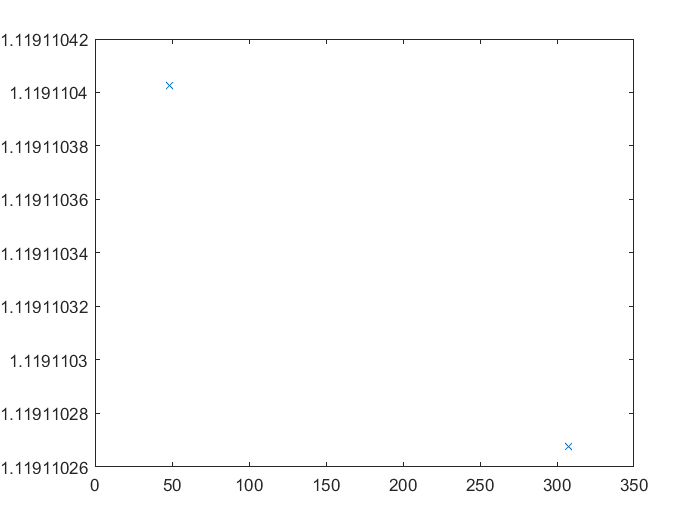

figure
plot(loc3,pks3,'X')

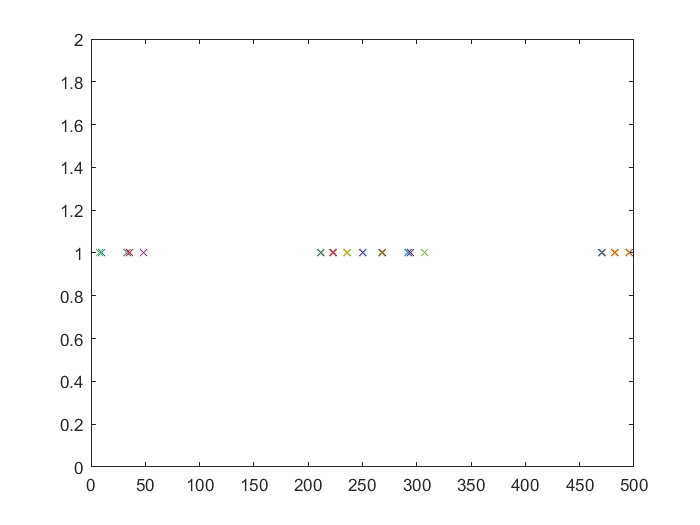


figure
plot(loc1,1,'X')
hold on
plot(loc2,1,'X')
plot(loc3,1,'X')

## **Time plot of peaks**

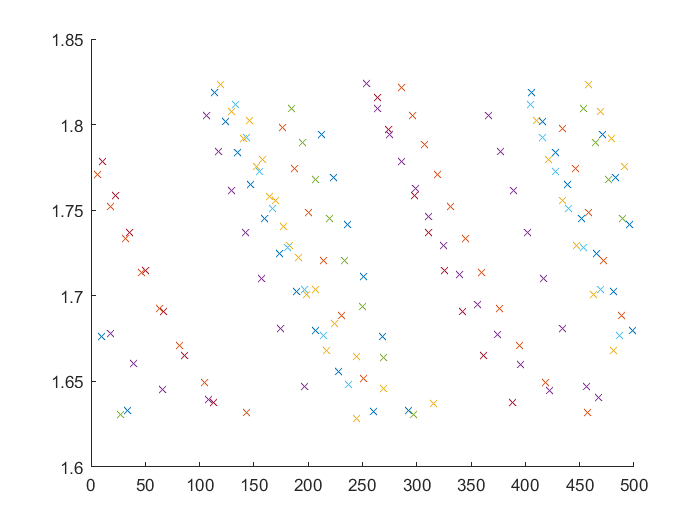

% bifurcation plot varying a parameter  
pksall=[];
figure 
hold on
for I=5:0.1:6
    a = 1;
    c = -3;
    d = 5; 
    s = 4;
    x0 =-1.3; 
    b=3;
    e=0.002;
    f = @(t,X)hindmarsh_rose(t,X,[a,c,d,s,x0,b,I,e]); 

    %first solve with relaxed tolerances over long period
    opts1 = odeset('RelTol',1e-6,'AbsTol',1e-8);
    [~,X]=ode45(f,[0,2000],[x0;6;1],opts1);

    %then use the evolved solution as the initial condition 
    %with tighter tolerances and shorter period
    opts2 = odeset('RelTol',1e-8,'AbsTol',1e-10);
    [T,X]=ode45(f,[0,500],X(end,:),opts2);



%[T,X]=ode45(f,[0,500],[x0,6,1]);

%peaks location for X(:,1)
[pks1,loc1]=findpeaks(X(:,1),T);

plot(loc1,pks1,'X')


%pksall=[pksall,pks1]


end
hold off

## Bifurcation diagram #1

figure1 = figure

figure1 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


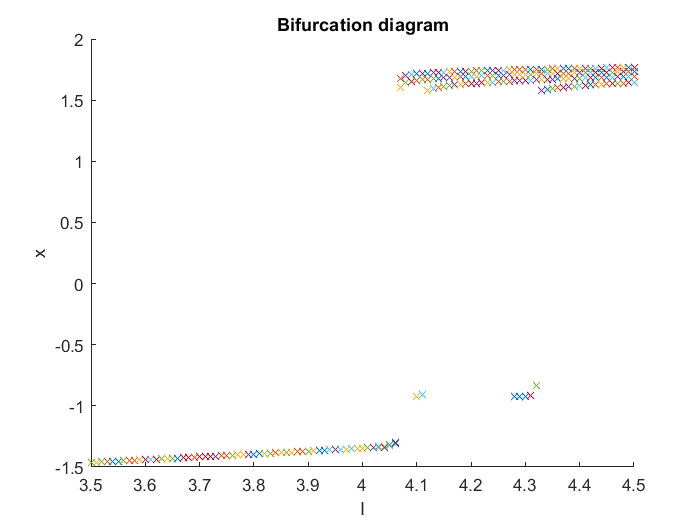

hold on
for I = 3.5:0.01:4.5
  a = 1;
  c = -3;
  d = 5; 
  s = 4;
  x0 =-1.3; 
  b=3;
  e=0.002;
  
  f = @(t,X)hindmarsh_rose(t,X,[a,c,d,s,x0,b,I,e]); 

  %first solve with relaxed tolerances over long period
  opts1 = odeset('RelTol',1e-6,'AbsTol',1e-8);
  [~,X]=ode45(f,[0,2000],[x0;6;1],opts1);

  %then use the evolved solution as the initial condition 
  %with tighter tolerances and shorter period
  opts2 = odeset('RelTol',1e-8,'AbsTol',1e-10);
  [T,X]=ode45(f,[0,500],X(end,:),opts2);
  
  pks1=findpeaks(X(:,1),T);
  plot(I, pks1, 'X')
end
title('Bifurcation diagram');
xlabel('I');  ylabel('x');
set(gca, 'xlim', [3.5 4.5]);
hold off
saveas(figure1, 'bifurcation diagram.jpg')

## **Time series plot for "interesting" values of I**

**I = 4.1**

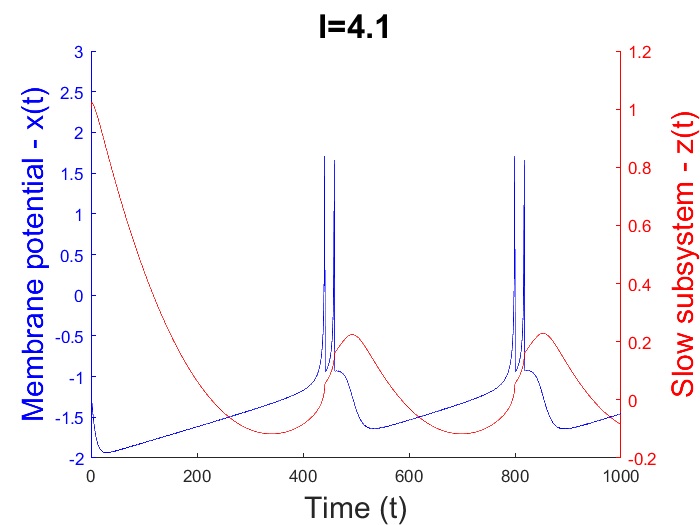


a = 1;
c = -3;
d = 5; 
s = 4;
x0 =-1.3; 
b=3;
I=4.1;
e=0.002;

f = @(t,X)hindmarsh_rose(t,X,[a,c,d,s,x0,b,I,e]); 
[T,X]=ode45(f,[0,1000],[x0,6,1]);

figure

hold on 

yyaxis left
plot(T,X(:,1),'Color','b')
ylabel('Membrane potential - x(t)','FontSize',18)
xlabel('Time (t)','FontSize',18)
set(gca,'ycolor','b')

yyaxis right
plot(T,X(:,3),'Color','r')
ylabel('Slow subsystem - z(t)','FontSize',18)
set(gca,'ycolor','r')

title('I=4.1','FontSize',20)

hold off

**I = 4.2**

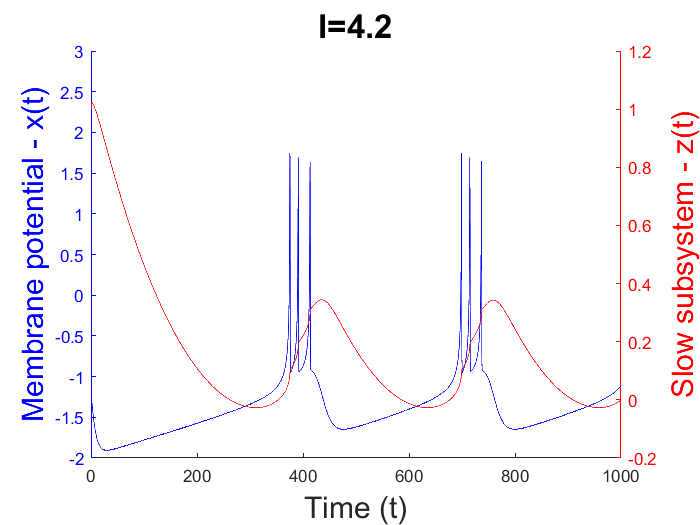

a = 1;
c = -3;
d = 5; 
s = 4;
x0 =-1.3; 
b=3;
I=4.2;
e=0.002;

f = @(t,X)hindmarsh_rose(t,X,[a,c,d,s,x0,b,I,e]); 
[T,X]=ode45(f,[0,1000],[x0,6,1]);

figure

hold on 

yyaxis left
plot(T,X(:,1),'Color','b')
ylabel('Membrane potential - x(t)','FontSize',18)
xlabel('Time (t)','FontSize',18)
set(gca,'ycolor','b')

yyaxis right
plot(T,X(:,3),'Color','r')
ylabel('Slow subsystem - z(t)','FontSize',18)
set(gca,'ycolor','r')

title('I=4.2','FontSize',20)

hold off

**I = 4.5**

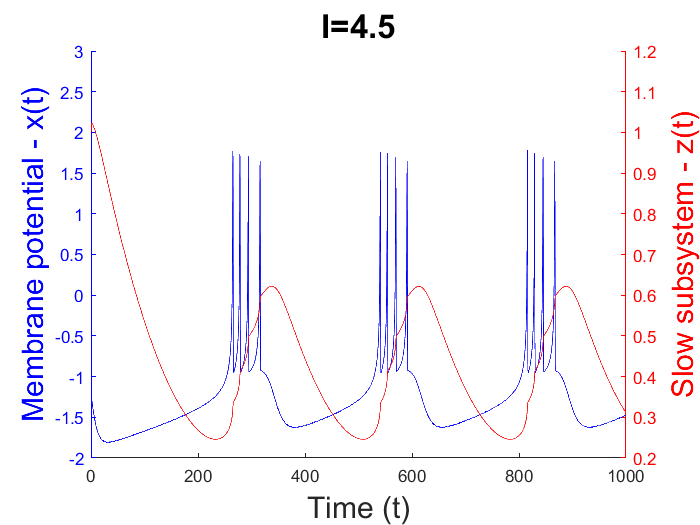

a = 1;
c = -3;
d = 5; 
s = 4;
x0 =-1.3; 
b=3;
I=4.5;
e=0.002;

f = @(t,X)hindmarsh_rose(t,X,[a,c,d,s,x0,b,I,e]); 
[T,X]=ode45(f,[0,1000],[x0,6,1]);

figure

hold on 

yyaxis left
plot(T,X(:,1),'Color','b')
ylabel('Membrane potential - x(t)','FontSize',18)
xlabel('Time (t)','FontSize',18)
set(gca,'ycolor','b')

yyaxis right
plot(T,X(:,3),'Color','r')
ylabel('Slow subsystem - z(t)','FontSize',18)
set(gca,'ycolor','r')

title('I=4.5','FontSize',20)

hold off

***period adding - COOL***

## Bifurcation diagram #2

figure2 = figure

figure2 =   Figure (1) with properties:

      Number: 1
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [488 342 560 420]
       Units: 'pixels'

  Show all properties


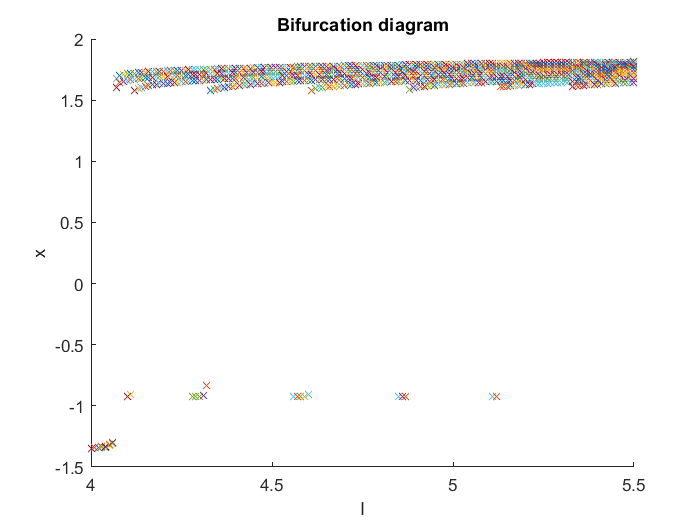

hold on
for I = 4:0.01:5.5
  a = 1;
  c = -3;
  d = 5; 
  s = 4;
  x0 =-1.3; 
  b=3;
  e=0.002;
  
  f = @(t,X)hindmarsh_rose(t,X,[a,c,d,s,x0,b,I,e]); 

  %first solve with relaxed tolerances over long period
  opts1 = odeset('RelTol',1e-6,'AbsTol',1e-8);
  [~,X]=ode45(f,[0,2000],[x0;6;1],opts1);

  %then use the evolved solution as the initial condition 
  %with tighter tolerances and shorter period
  opts2 = odeset('RelTol',1e-8,'AbsTol',1e-10);
  [T,X]=ode45(f,[0,500],X(end,:),opts2);
  
  pks1=findpeaks(X(:,1),T);
  plot(I, pks1, 'X')
end
title('Bifurcation diagram');
xlabel('I');  ylabel('x');
set(gca, 'xlim', [4 5.5]);
hold off
saveas(figure2, 'bifurcation diagram2.jpg')

# **Lyapunov exponent**

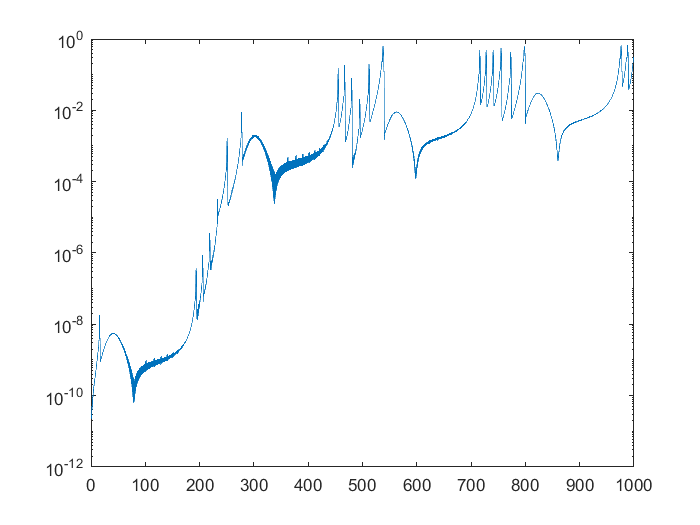

 opts = odeset('AbsTol',1e-8,'RelTol',1e-10);

a = 1;
c = -3;
d = 5; 
s = 4;
x0 =-1.3; 
b=3;
e=0.002;
I=5;
  
f = @(t,X)hindmarsh_rose(t,X,[a,c,d,s,x0,b,I,e]);

[t,X]=ode45(f,[0,1e4],5*randn(3,1)); 

X0=X(end,:);

% Trajectory for X(0)=X0
T = linspace(0,1e3,1e5);
[t,sol1] = ode45(f,T,X0);

% Trajectory for X(0)=X0+P
P = 1e-10*randn(1,3); %Small perturbation
[t,sol2] = ode45(f,T,X0+P);

% Plot the log of |sol2-sol1|/|sol2|
D = rms(sol2-sol1,2)./rms(sol2,2);
semilogy(T,D)

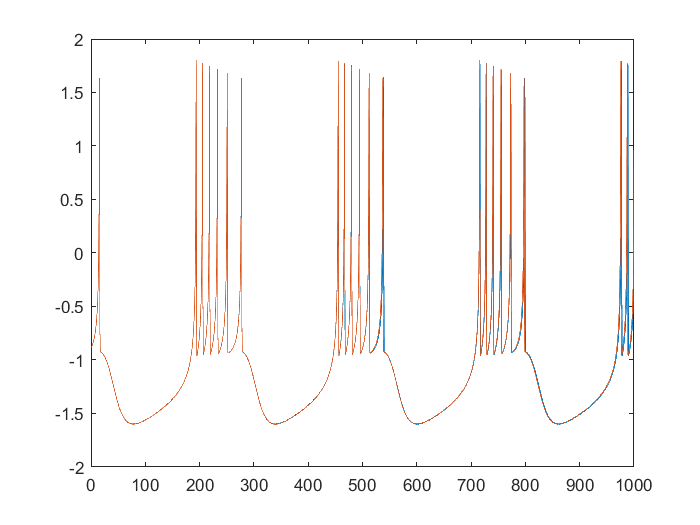


plot(T,sol1(:,1),T,sol2(:,1))